# 利用散点估计外接圆

一般而言，对散点进行圆弧拟合采用最小二乘方法，而最小二乘不可避免的需要求解线性方程组，且矩阵的维度随着散点的数量增加而增加，这使得在嵌入式设备上用于估计道路的一定范围的曲率较为耗费算力。

那么肯定会有人说，如果我基于散点得到道线的解析描述，这样不就可以得到求出曲率，不这样做的原因有以下两点：

- 这样求出曲率是逐点的曲率，在实际问题中一定范围的平均曲率则更为实用

- 求出的道线的多项式无论是基于 Hough 变换还是最小二乘本身是有一定的误差，而且由于求曲率需要涉及到高阶导数，会使得拟合的误差对于结果影响很大

所以下面介绍一种在一定前提下对于最小二乘法的简化方法

## 算法原理

圆方程可以写成：


$$(x-x_c)^2 + (y - y_c)^2 = R^2$$


那么散点拟合圆的距离平方和就要求最小：


$$min \sum_{i}^n (\sqrt{(x_i-x_c)^2 + (y_i - y_c)^2} - R)^2$$


注意，上式难以直接求解，需要形成矩阵方程来求解。

**为了简化，我们退而求其次，求解下式**


$$min \sum_{i}^n ((x_i-x_c)^2 + (y_i - y_c)^2 - R^2)^2$$


本质上是将原式展开并采用一个很强的假设：


$$\sqrt{(x_i-x_c)^2 + (y_i - y_c)^2} - R = \delta R \to 0  \quad \forall i \leq n$$


显然，这个假设当采样点都几乎分布在圆弧的附近时才会成立，所以这个方法会非常容易受到离群点的影响。

## 推导

那么我们进一步可以定义一个辅助函数：


$$g(x_c,y_c,R) = (x_i-x_c)^2 + (y_i - y_c)^2 - R^2$$


问题就转变为


$$min \sum_i^n g(x_c,y_c,R) ^2$$


为无约束优化问题，其最值必要条件为各方向偏导数为0，分别有


$$
\frac{\partial f}{\partial R} =-2 R \times \sum\left(\left(x_{i}-x_{c}\right)^{2}+\left(y_{i}-y_{c}\right)^{2}-R^{2}\right) 
=-2 R \times \sum g\left(x_{i}, y_{i}\right)=0
$$


显然圆的半径不为 0 ，则有 


$$\sum g\left(x_{i}, y_{i}\right)=0$$


进一步从对 $x_c \quad y_c $ 导数可以得到


$$\sum x_{i} g\left(x_{i}, y_{i}\right)=0 \\
\sum y_{i} g\left(x_{i}, y_{i}\right)=0$$


设置


$$u_{i} =x_{i}-x \\
u_{C} =x_{C}-\bar{x} \\
v_{i} =y_{i}-\bar{y} \\
v_{C} =y_{c}-\bar{y}$$


其中


$$\bar{x}=\sum x_{i} / N \\
\bar{y}=\sum y_{i} / N$$


那么有


$$\sum u_{i} g\left(u_{i}, v_{i}\right)=0 \\
\sum v_{i} g\left(u_{i}, v_{i}\right)=0$$


展开有


$$\sum\left(u_{i}^{3}-2 u_{i}^{2} u_{c}+u_{i} u_{c}^{2}+u_{i} v_{i}^{2}-2 u_{i} v_{i} v_{c}+u_{i} v_{c}^{2}-u_{i} R^{2}\right)=0 \\
\sum\left(u_{i}^{2} v_{i}-2 u_{i} v_{i} u_{c}+v_{i} u_{c}^{2}+v_{i}^{3}-2 v_{i}^{2} v_{c}+v_{i} v_{c}^{2}-v_{i} R^{2}\right)=0
$$


带入 $\sum u_i =0 \quad \sum v_i =0$


$$\sum\left(u_{i}^{3}-2 u_{i}^{2} u_{C}+u_{i} v_{i}^{2}-2 u_{i} v_{i} v_{C}\right)=0 \\
\sum\left(u_{i}^{2} v_{i}-2 u_{i} v_{i} u_{C}+v_{i}^{3}-2 v_{i}^{2} v_{C}\right)=0
$$


进一步定义


$$S_{u u u} =\sum u_{i}^{3} \\
S_{v v v} =\sum v_{i}^{3} \\
S_{u u} =\sum u_{i}^{2} \\
S_{v v} =\sum v_{i}^{2} \\
S_{u v} =\sum u_{i} v_{i} \\
S_{u u v} =\sum u_{i}^{2} v_{i} \\
S_{u v v} =\sum u_{i} v_{i}^{2}$$


则上面的求和式可以写成


$$S_{u u} u_{C}+S_{u v} v_{C}=\frac{S_{u u u}+S_{u v v}}{2} \\
S_{u v} u_{C}+S_{v v} v_{C}=\frac{S_{u u v}+S_{v v v}}{2}$$


则可以求出


$$u_{C} =\frac{S_{u u v} S_{u v}-S_{u u u} S_{v v}-S_{u v v} S_{v v}+S_{u v} S_{v v v}}{2\left(S_{u v}^{2}-S_{u u} S_{v v}\right)} \\
v_{C} =\frac{-S_{u u} S_{u u v}+S_{u u u} S_{u v}+S_{u v} S_{u v v}-S_{u u} S_{v v v}}{2\left(S_{u v}^{2}-S_{u u} S_{v v}\right)}\\
R^{2}=\sum\left(\left(x_{i}-x_{c}\right)^{2}+\left(y_{i}-y_{c}\right)^{2}\right)
$$


## Matlab 实现

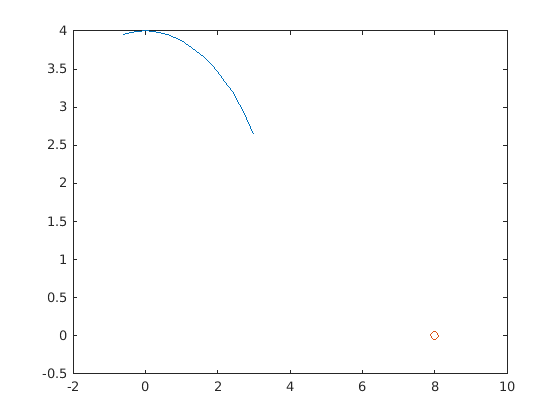

% Sample Generation
clear; 
R = 4 ;

x = -0.6:0.2:3;
y = sqrt(R^2 - x.^2);

[Flag,R,Xc,Yc] = circleFit(x,y);

plot(x,y);
hold on;
scatter(Xc,Yc);

function [Flag,R,Xc,Yc] = circleFit(X_in,Y_in)

    
    sum_x = 0;
    sum_y = 0;
    sum_x2 = 0;
    sum_y2 = 0;
    sum_x3 = 0;
    sum_y3 = 0;
    sum_xy = 0;
    sum_x1y2 = 0;
    sum_x2y1 = 0;
    
    
    
    N = length(X_in); 
    
    for i = 1 : N
        x = X_in(i);
        y = Y_in(i);
        x2 = x*x;
        y2 = y*y;
        sum_x = sum_x + x;
        sum_y = sum_y + y;
        sum_x2 = sum_x2 + x2;
        sum_y2 = sum_y2 + y2;
        sum_x3 = sum_x3 + x2*x;
        sum_y3 = sum_y3 + y2*y;
        sum_xy = sum_xy + x*y;
        sum_x1y2 = sum_x1y2 + x*y2;
        sum_x2y1 = sum_x2y1 + x2*y;
    end
    
    C = N * sum_x2 - sum_x * sum_x;
    D = N * sum_xy - sum_x * sum_y;
    E = N * sum_x3 + N * sum_x1y2 - (sum_x2 + sum_y2) * sum_x;
    G = N * sum_y2 - sum_y * sum_y;
    H = N * sum_x2y1 + N * sum_y3 - (sum_x2 + sum_y2) * sum_y;
    if abs(C * G - D * D) < 10^-6 || abs((D * D - G * C)) < 10^-6
        
        Xc = 0;
        Yc = 0;
        R = 0;
        Flag = uint8(0);
       
    else
        a = (H * D - E * G) / (C * G - D * D);
        b = (H * C - E * D) / (D * D - G * C);
        c = -(a * sum_x + b * sum_y + sum_x2 + sum_y2) / N;
    
        Xc = -0.5*c;
        Yc = -0.5*b;
        R = sqrt(a*a + b*b - 4*c)/2;
        Flag = uint8(1);
    end
    
end